# Chapter 08: Dimension Reduction

close all; clear all;
warning('off','all')

## Principal component analysis (PCA)

The $k$-dimensional linear subspace $\mathcal{W}$ of $\mathbb{R}^d$ that minimizes 


$$\sum_{i=1}^{m} \mathrm{dist}_{\ell_2}(x^{(i)},\mathcal{W})^2$$


is spanned by the first $k$ left singular vectors of the data matrix $X \in \mathbb{R}^{d \times m}$, where the $i$th column of the data matrix $X$ is $x^{(i)} \in \mathbb{R}^d$. 

One uses both the built-in svd command and the eigendecomposition method to compute the first $k
$ left singular vectors of $X$ and compare the computation times.

% generate high-dimensional data for principal component analysis
d = 1000;             % original dimension
m = 500;              % number of datapoints
k = 100;              % reduced dimension
X = rand(d,m);        % generate random datapoints

% compute the first k left singular vectors of X via the built-in svd command 
% and record the computation time
tic;
[U_svd,~,~] = svd(X);
time_svd = toc;
U_svd = U_svd(:,1:k);
fprintf('The computation time for the built-in svd command is %.8f seconds',time_svd)

The computation time for the built-in svd command is 0.01118994 seconds

% compute the first k left singular vectors of X via the eigendecomposition of X^T*X 
% and record the computation time
tic;
[V,D] = eig(X'*X,'vector');
% compute the left singular vectors of X
time_eig = toc;
U_eig = X * V(:,m-k+1:end) * diag(1./sqrt(D(m-k+1:end,:)));
U_eig = fliplr(U_eig);
fprintf('The computation time for eigendecomposition method is %.8f seconds',time_eig)

The computation time for eigendecomposition method is 0.02066470 seconds

## Johnson-Lindenstrauss lemma

close all; clear all;
% generate high-dimensional data for the Johnson-Lindenstrauss lemma
d = 100000;                          % original dimension
m = 1000;                            % number of datapoints
X = randn(d,m)*rand(m,m)/m;          % generate random datapoints
delta = 1/5;
k = ceil(18*log(m) / (delta^2))      % reduced dimension

k = 3109

A = randn(k,d) / sqrt(k);            % the matrix used in the Johnson-Lindenstrauss lemma

Below, one computes the 3 exact nearest neighbors and 3 JL-based approximate nearest neighbors for the first datapoint. The indices of nearest neighbors and the distances to the nearest neighbors are returned. One also compares computation times.

n = 3;
tic;
% compute the distance from x^(1) to all the other x^(i)'s
distances_ex = pdist2(X(:,1)',X(:,2:end)');
% return the n smallest values and the indices where they occur
[dist_ex,idx_ex] = mink(distances_ex,n);
time_ex = toc;
fprintf('Three exact nearest neighbors found at indices %d,%d,%d with distances %.4f,%.4f,%.4f in %.8f seconds.',...
    1+idx_ex,dist_ex,time_ex)

Three exact nearest neighbors found at indices 678,497,795 with distances 3.7918,3.8086,3.8094 in 2.34745874 seconds.

X_JL = A*X;
tic;
% compute the distance from Ax^(1) to all the other Ax^(i)'s
distances_JL = pdist2(X_JL(:,1)',X_JL(:,2:end)');
% return the indices where the n smallest values occur
[~,idx_JL] = mink(distances_JL,n);
time_JL = toc;
% determine the distances from x^(1) to the approximate nearest neighbors
dist_JL = distances_ex(idx_JL);
fprintf('Three approximate nearest neighbors found at indices %d,%d,%d with distances %.4f,%.4f,%.4f in %.8f seconds.',...
    1+idx_JL,dist_JL,time_JL)

Three approximate nearest neighbors found at indices 497,678,91 with distances 3.8086,3.7918,3.8179 in 0.03549321 seconds.

## Locally linear embedding (LLE)

A function implementing the LLE procedure is defined at the end of the document.

### Example 1: Swiss-Roll

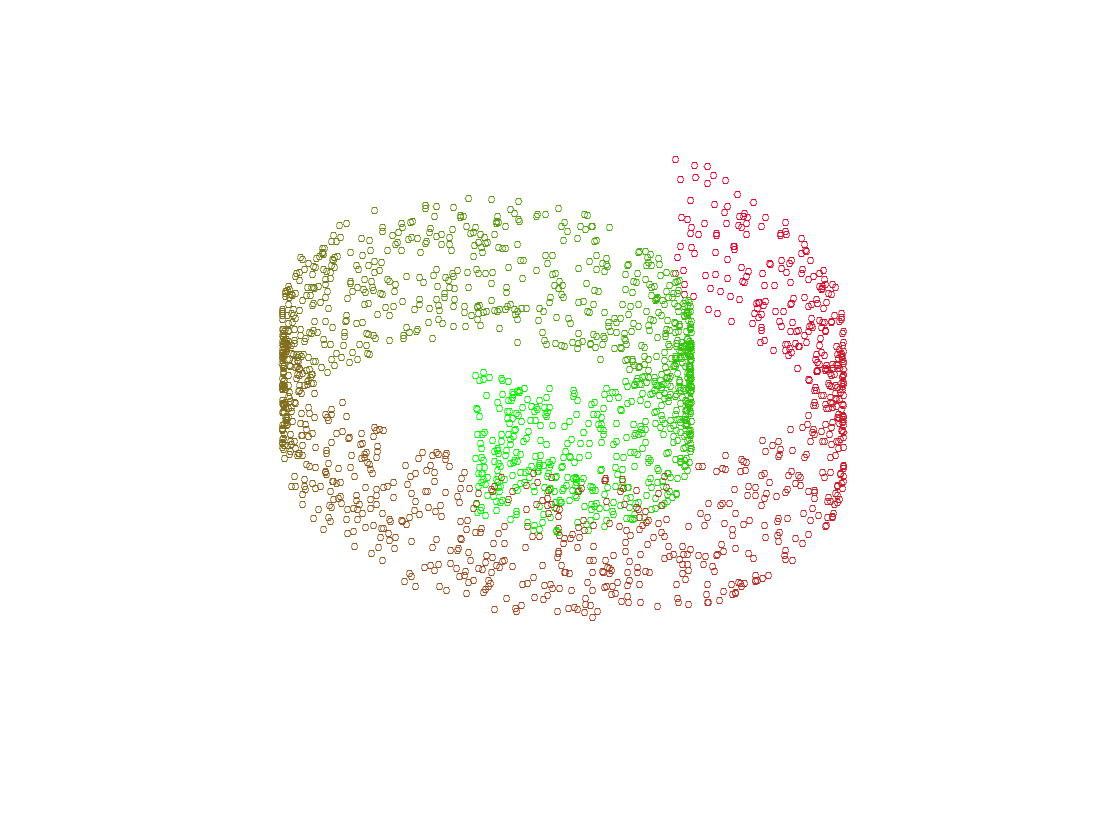

close all; clear all;
% generate datapoints along a nonlinear manifold
m = 2000;
t = (3*pi/2)*(1+2*rand(m,1));  
x = t.*cos(t);
y = t.*sin(t);
z = 21*rand(m,1);
% visualize the datapoints
pix = (t-min(t))/(max(t)-min(t));
color = [0.9*pix, 1-pix, 0.2*pix];
scatter3(x,y,z,12,color,'o');
set(gca,'XTick',[],'Xcolor','none')
set(gca,'YTick',[],'Ycolor','none')
set(gca,'ZTick',[],'Zcolor','none')
view([30 70])

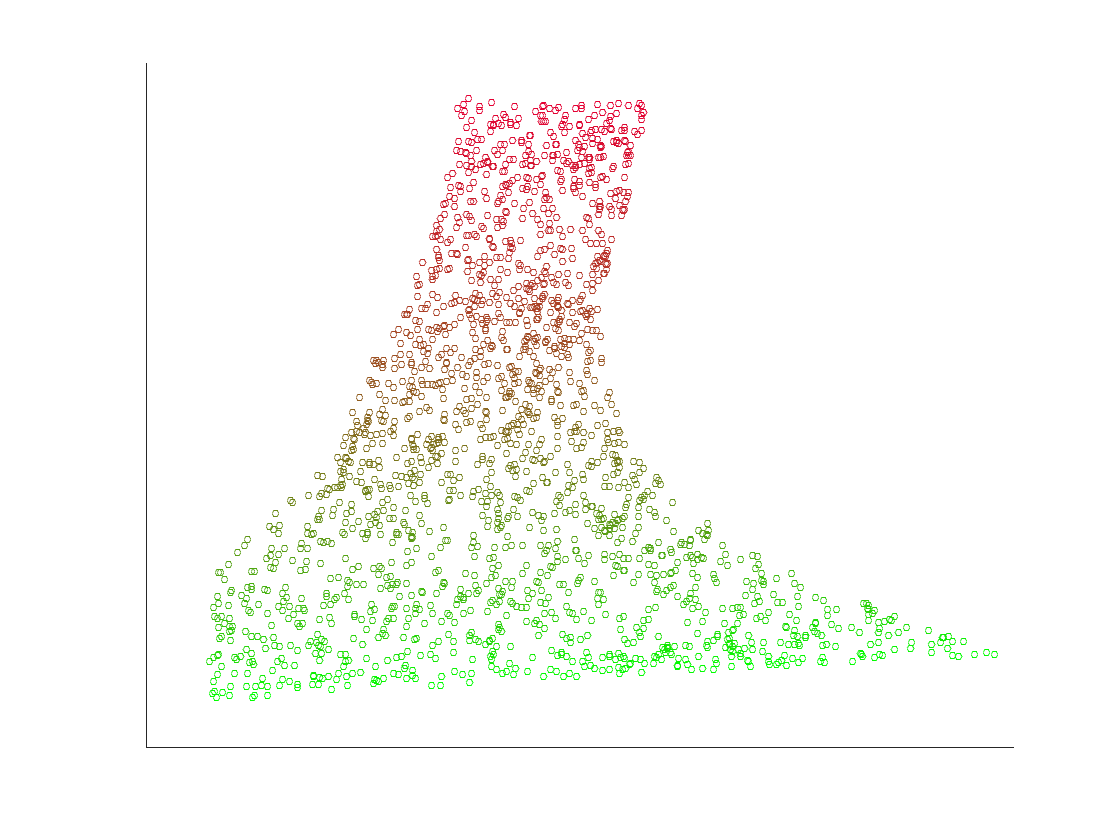

% perform LLE for the given dataset and plot the output
X = [x,y,z]';
n = 10;                   % number of nearest neighbors  
k = 2;                              % reduced dimension       
Z = lle(X,n,k);
scatter(Z(1,:),Z(2,:),12,color,'o')
set(gca,'XTick',[])
set(gca,'YTick',[])

## Example 2: datapoints along the axes

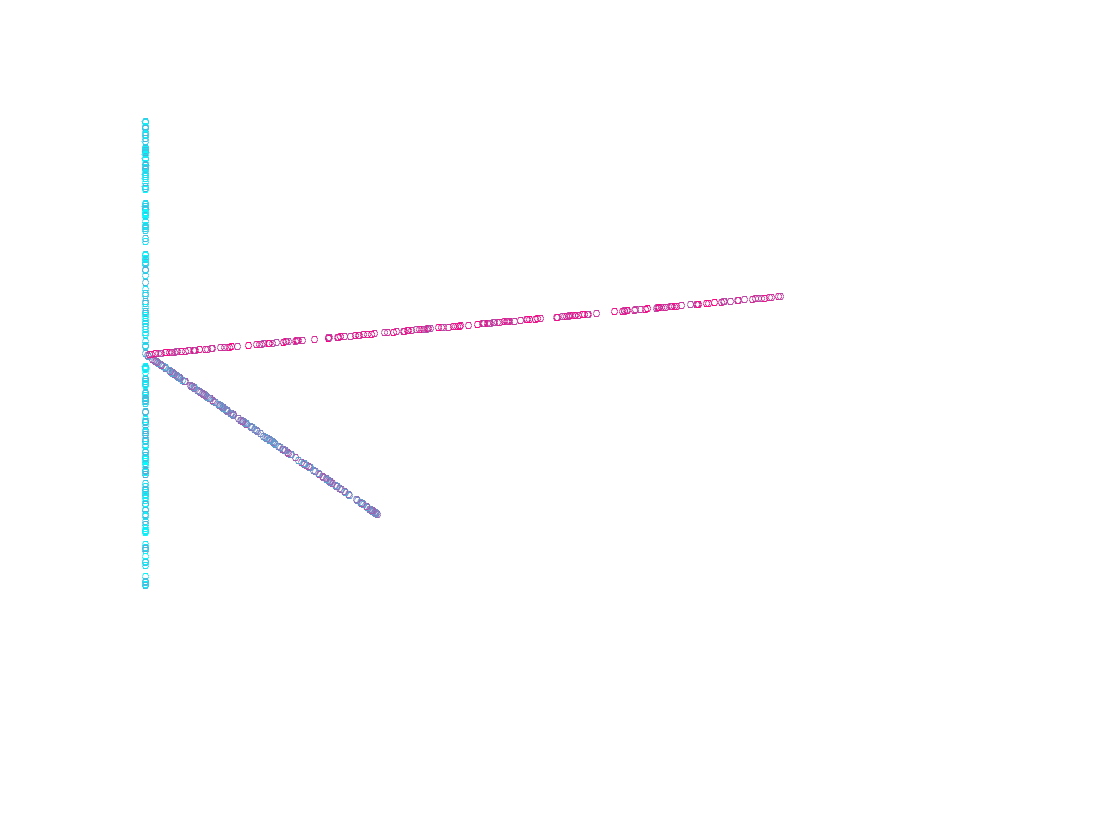

% generate the datapoints in xyz axes
m = 600;     % chose m as a multiple of 3
x = [rand(m/3,1);zeros(m/3,1);zeros(m/3,1)];
y = [zeros(m/3,1);rand(m/3,1);zeros(m/3,1)];
z = [zeros(m/3,1);zeros(m/3,1);2*rand(m/3,1)-1];
% visualize the datapoints
pix = linspace(0,1,m)';
color = [1-pix, pix, (1+pix)/2];
scatter3(x,y,z,12,color,'o');
set(gca,'XTick',[],'Xcolor','none')
set(gca,'YTick',[],'Ycolor','none')
set(gca,'ZTick',[],'Zcolor','none')
view([20 -20])

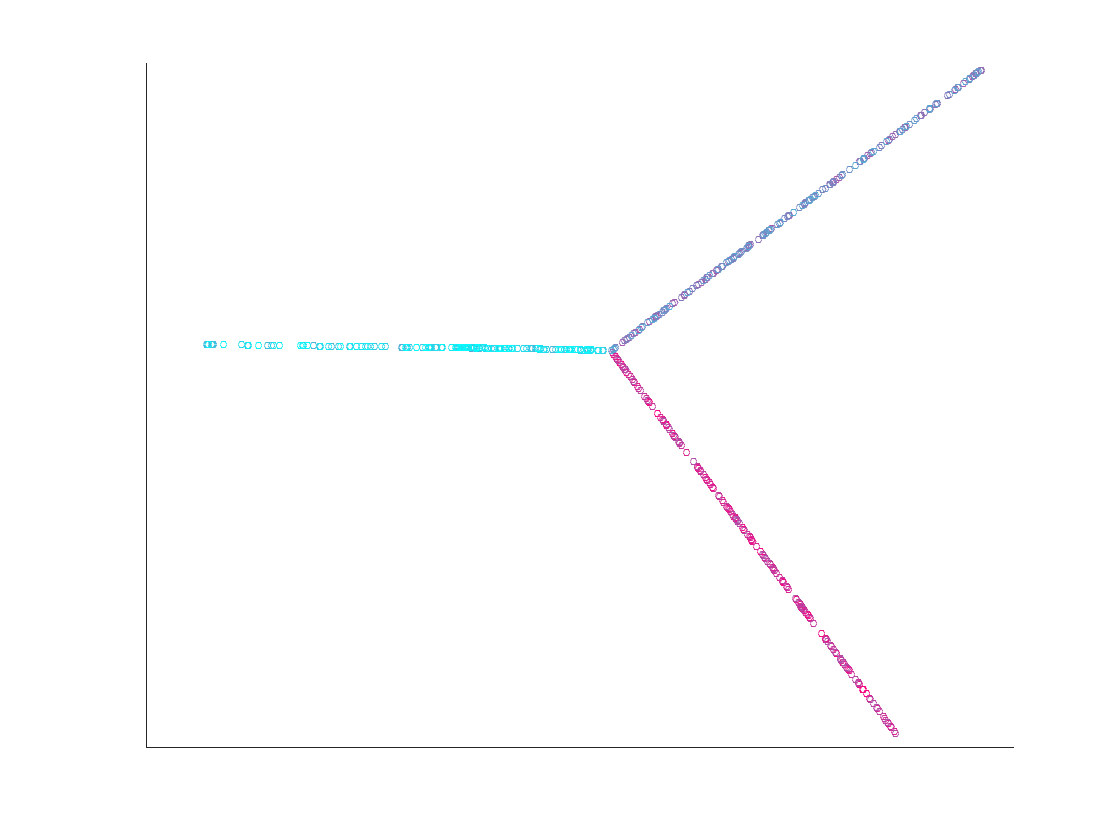

% perform LLE for the given dataset and plot the output
X = [x,y,z]';
n = 10;                   % number of nearest neighbors  
k = 2;                              % reduced dimension       
Z = lle(X,n,k);
scatter(Z(1,:),Z(2,:),12,color,'o')
set(gca,'XTick',[])
set(gca,'YTick',[])

### The function defined below perfoms the locally linear embedding procedure on the dataset X using n nearest neighbors to ouput points in dimension k.

function Z = lle(X,n,k)
% X is a matrix with m datapoints in R^d as its columns 
% n is the number of nearest neighbors used
% k is the projected dimension

[d,m] = size(X);  % d is the original dimension (k,n<=d) and  m is the number of datapoints

% Step 1: compute pairwise distances and find neighbors
D = pdist2(X',X');
[~,index] = sort(D);
idx = index(2:n+1,:);

% Step 2: compute the weights w^(i)
if n > d       % this is not the situation considered in Section 8.3
    reg = 1e-3;    % a regularization parameter
else
    reg = 0;
end
W = zeros(m,m);
for i=1:m
   M = X(:,i) - X(:,idx(:,i));
   G = M'*M; 
   G = G + reg*trace(G)*eye(n,n);
   w = G\ones(n,1);
   W(idx(:,i),i) = w/(sum(w));   
end

% Step 3: compute the eigenvectors of (I-W)*(I-W)' and return the outputs
[U,~] = eigs((eye(m)-W)*(eye(m)-W)',k+1,'smallestabs');
Z = U(:,k+1:-1:2)';

end